# Lab #2

## Part C)

### Q1, 2

cd ~/Downloads/Yuqi/

flex1raw = readtable('YuqiFlex1Raw.csv');

flex1filtered = readtable('YuqiFlex1Filtered.csv');

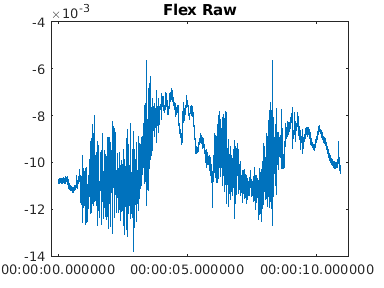

plot(flex1raw.ElapsedTime, flex1raw.BICEP)
title("Flex Raw")

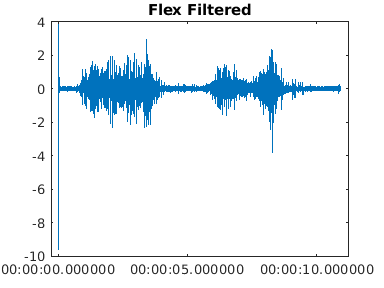

plot(flex1filtered.ElapsedTime, flex1filtered.BICEP)
title("Flex Filtered")

noise = flex1raw.BICEP - flex1filtered.BICEP;
plot(flex1filtered.ElapsedTime, noise)
title("Noise")

### Q3

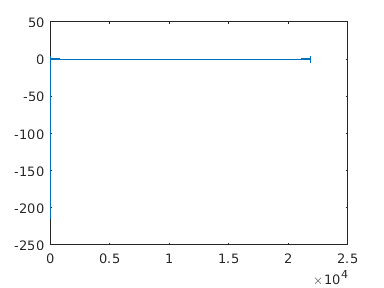

fftraw = real(fft(flex1raw.BICEP));


d = designfilt('bandpassiir','FilterOrder',4, ...
    'HalfPowerFrequency1',10,'HalfPowerFrequency2',500, ...
    'SampleRate',21871/11);

### Q4

% removing DC offset
fftraw = fftraw-mean(fftraw);
% fullwave rectification
fftraw = abs(fftraw);

### Q5

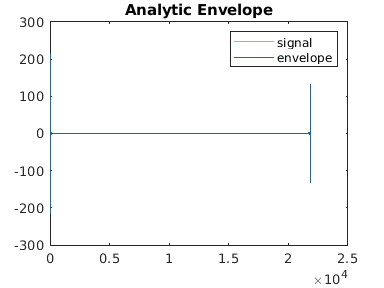

envelope(fftraw)

### Q6

Area = trapz(fftraw)

Area = 706.2721

### Q7

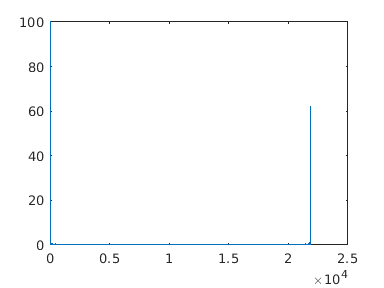

normalizedRaw = envelope(fftraw)/max(fftraw)*100;
plot(normalizedRaw)

## Part D)

### Q3.

raw = readtable('YuqiFlex1Raw.csv');